clear all;
%close all;
addpath('utility_functions');

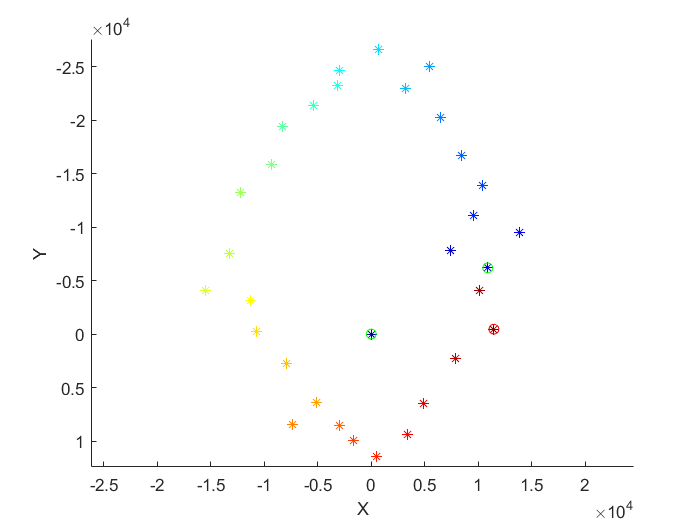

 
hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\2022_11_23_15_10_06\2022_11_23_14_58_10.txt';
%hexa_file_name = 'C:\Users\jonas\Desktop\30220 Synthesis in Earth and Space Physics Fall 22\2022_12_06_13_41_24\2022_12_06_13_29_22.txt';

file = fileread(hexa_file_name);
hexa_string_all(1,:) = strfind(file,"X: ");
hexa_string_all(2,:) = strfind(file,", Y");
hexa_string_all(3,:) = strfind(file,"Y: ");
hexa_string_all(4,:) = strfind(file,", Z");
hexa_string_all(5,:) = strfind(file,"Z: ");
hexa_string_all(6,:) = strfind(file,", U");
hexa_string_all(7,:) = strfind(file,"U: ");
hexa_string_all(8,:) = strfind(file,", V");
hexa_string_all(9,:) = strfind(file,"V: ");
hexa_string_all(10,:) = strfind(file,", W");
hexa_string_all(11,:) = strfind(file,"W: ");
for i=1:size(hexa_string_all,1)
    hexa_string(i,:) = hexa_string_all(i,2:2:end);
end
hexa_string(12,:) = strfind(file,", T");
 
for j=1:size(hexa_string,2)
    for i=1:size(hexa_string,1)/2
        hexa_pos(i,j) = double(string(file(hexa_string(i*2-1,j)+3:hexa_string(i*2,j)-1)));
    end
end
hexa_pos(1,:) = hexa_pos(1,:)*10^3;
hexa_pos(2,:) = hexa_pos(2,:)*10^3;
hexa_pos(3,:) = hexa_pos(3,:)*10^3;
hexa_pos(4,:) = hexa_pos(4,:);
hexa_pos(5,:) = hexa_pos(5,:);
 
sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\2022_11_23_15_10_06\download\';
%sli_file_path = 'C:\Users\jonas\Desktop\30220 Synthesis in Earth and Space Physics Fall 22\2022_12_06_13_41_24\download\';
sli_files = dir([sli_file_path '*.unk']);
for i=1:length(sli_files)
    [h,sli(i,:),m] = readAscImage([sli_file_path sli_files(i).name]);  
end
hexa_pos(:,1:length(sli_files)) = hexa_pos(:,size(hexa_pos,2)-length(sli_files)+1:end) ;
%Cam rotation
best_angle_x = 18.27;
best_angle_y = -0.38;
best_angle_z = 0.2700;
pivot_point = 190*10^3; %um
c2x_y = 23*10^3;        %um
x2c_z = 22997;          %um
 
x_ray_pos = zeros(3,length(sli_files));
x_ray_pos(3,:) = pivot_point;
for i=1:length(sli_files)
    R_hex = createRotationMatrix(hexa_pos(6,i),hexa_pos(5,i),hexa_pos(4,i));
    x_ray_pos(:,i) = R_hex * x_ray_pos(:,i);
    x_ray_pos(:,i) = x_ray_pos(:,i) + hexa_pos(1:3,i);
end
colors = jet(size(sli,1));
figure(1);
clf
hold on;
for i=1:size(x_ray_pos,2)
    plot3(x_ray_pos(1,i),x_ray_pos(2,i),x_ray_pos(3,i),'*-','color',colors(i,:))
end
plot3(x_ray_pos(1,1),x_ray_pos(2,1),x_ray_pos(3,1),'og')
plot3(x_ray_pos(1,3),x_ray_pos(2,3),x_ray_pos(3,3),'og')
plot3(x_ray_pos(1,end),x_ray_pos(2,end),x_ray_pos(3,end),'or')
axis equal;
axis ij
xlabel("X")
ylabel("Y")

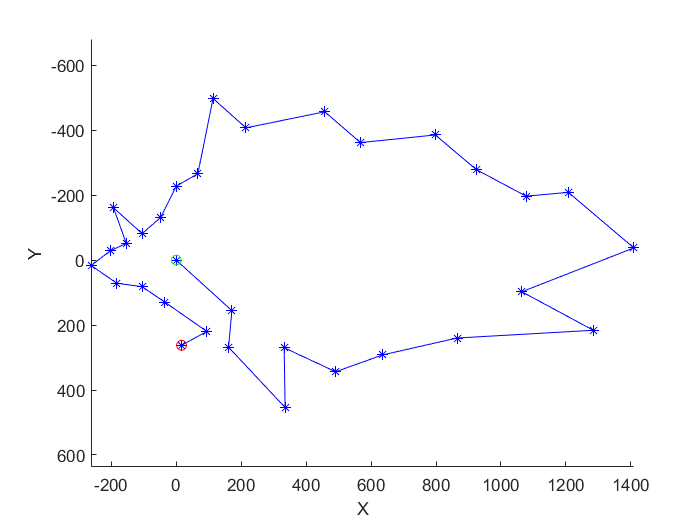

figure(2);
clf
hold on;
plot(hexa_pos(1,:),hexa_pos(2,:),'b*-')
plot(hexa_pos(1,1),hexa_pos(2,1),'og')
plot(hexa_pos(1,end),hexa_pos(2,end),'or')
axis equal;
axis ij
xlabel("X")
ylabel("Y")

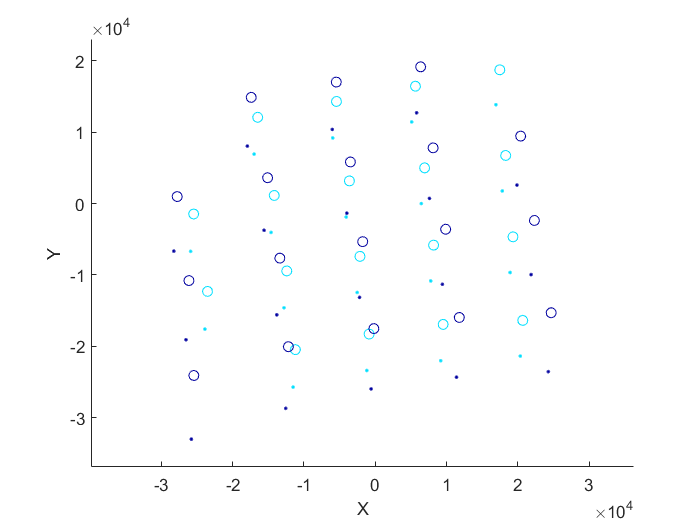

 
% Rotate and translate to "sensor frame"
for i=1:size(sli,1)
    temp = sli(i).sliData.Q'; 
    temp(4,:) = 1;
    sli_data_rot{i}.Q = temp;
    %sli_data_cen{i}.cen = sli(i).sliData.cen;
    T = [0 c2x_y pivot_point-x2c_z]';
    R = createRotationMatrix(best_angle_z,best_angle_y,best_angle_x);
    P = [R T];
    sli_data_rot{i}.Q = P*sli_data_rot{i}.Q;
end
figure(3)
clf;
hold on;
for i=[1 11]%:size(sli,1)
    plot3(sli_data_rot{i}.Q(1,:),sli_data_rot{i}.Q(2,:),sli_data_rot{i}.Q(3,:),'.','color',colors(i,:))
    plot3(sli(i).sliData.Q(:,1),sli(i).sliData.Q(:,2),sli(i).sliData.Q(:,3),'o','color',colors(i,:))
end
axis equal
xlabel("X")
ylabel("Y")

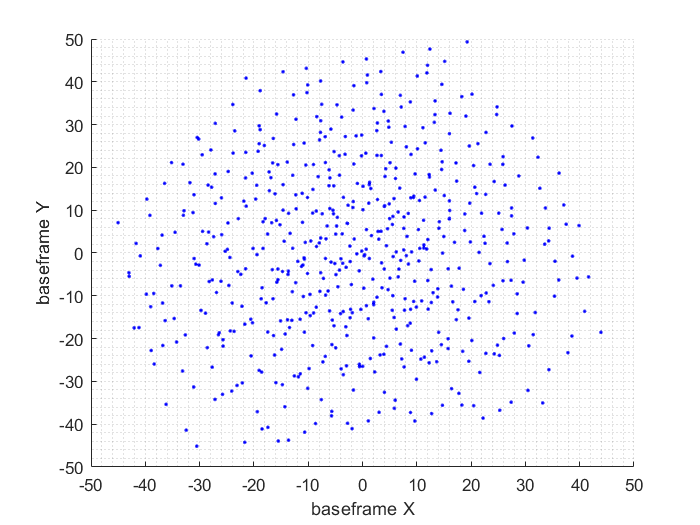

 
sli_data_hexa = sli_data_rot;
% Rotate and translate to "base frame"
for i=1:size(sli,1)
    sli_data_hexa{i}.Q(4,:) = 1;
    R_hex = createRotationMatrix(-hexa_pos(6,i),-hexa_pos(5,i),-hexa_pos(4,i));
    R_hex = createRotationMatrix(hexa_pos(6,i),hexa_pos(5,i),hexa_pos(4,i));
    T_hex = [hexa_pos(1:3,i)];
    P_hex = [R_hex' T_hex];
    sli_data_hexa_rot{i}.Q = P_hex * sli_data_hexa{i}.Q;
end
 
figure(4)
clf
hold on;
for i=1:size(sli_data_hexa_rot,2)
%     plot3(sli_data_hexa_rot{i}.Q(1,:)/1000,sli_data_hexa_rot{i}.Q(2,:)/1000,sli_data_hexa_rot{i}.Q(3,:)/1000,'.','color',colors(i,:))
    plot3(sli_data_hexa_rot{i}.Q(1,:)/1000,sli_data_hexa_rot{i}.Q(2,:)/1000,sli_data_hexa_rot{i}.Q(3,:)/1000,'.b')
%     plot3(mean(sli_data_hexa_rot{i}.Q(1,:))/1000,mean(sli_data_hexa_rot{i}.Q(2,:))/1000,mean(sli_data_hexa_rot{i}.Q(3,:))/1000,'*','color',colors(i,:),'markersize',10)
end
grid minor;
%axis equal
%axis ij;
xlabel("baseframe X")
ylabel("baseframe Y")
zlabel("baseframe Z")

x = [];
y = [];
z = [];
for i=1:size(sli_data_hexa_rot,2)
    x = [x sli_data_hexa_rot{i}.Q(1,:)/1000];
    y = [y sli_data_hexa_rot{i}.Q(2,:)/1000];
    z = [z sli_data_hexa_rot{i}.Q(3,:)/1000];
end
tri = delaunay(x,y);
figure
trisurf(tri,x,y,z)
% axis equal
xlabel("baseframe X")
ylabel("baseframe Y")
zlabel("baseframe Z")
range(z)

ans = 1.3950

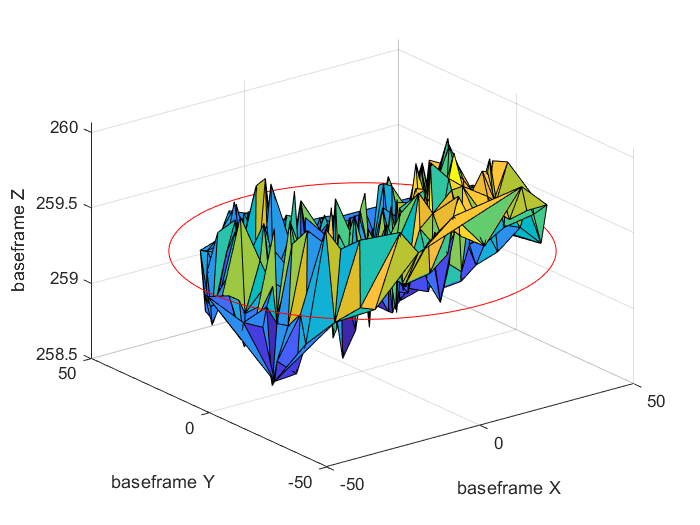

hold on
circ_x = cosd(1:360);
circ_y = sind(1:360);
circ_r = 50;
plot3(circ_x*circ_r, circ_y*circ_r, mean(z)*ones(size(circ_x)), 'r')

% surf(sli_data_hexa_rot{i}.Q(1,:)/1000,sli_data_hexa_rot{i}.Q(2,:)/1000,sli_data_hexa_rot{i}.Q(3,:)/1000)
